# Lab 12 SNS

## Syed Muhammad Asad Ali

### sa09475

#### Task 1

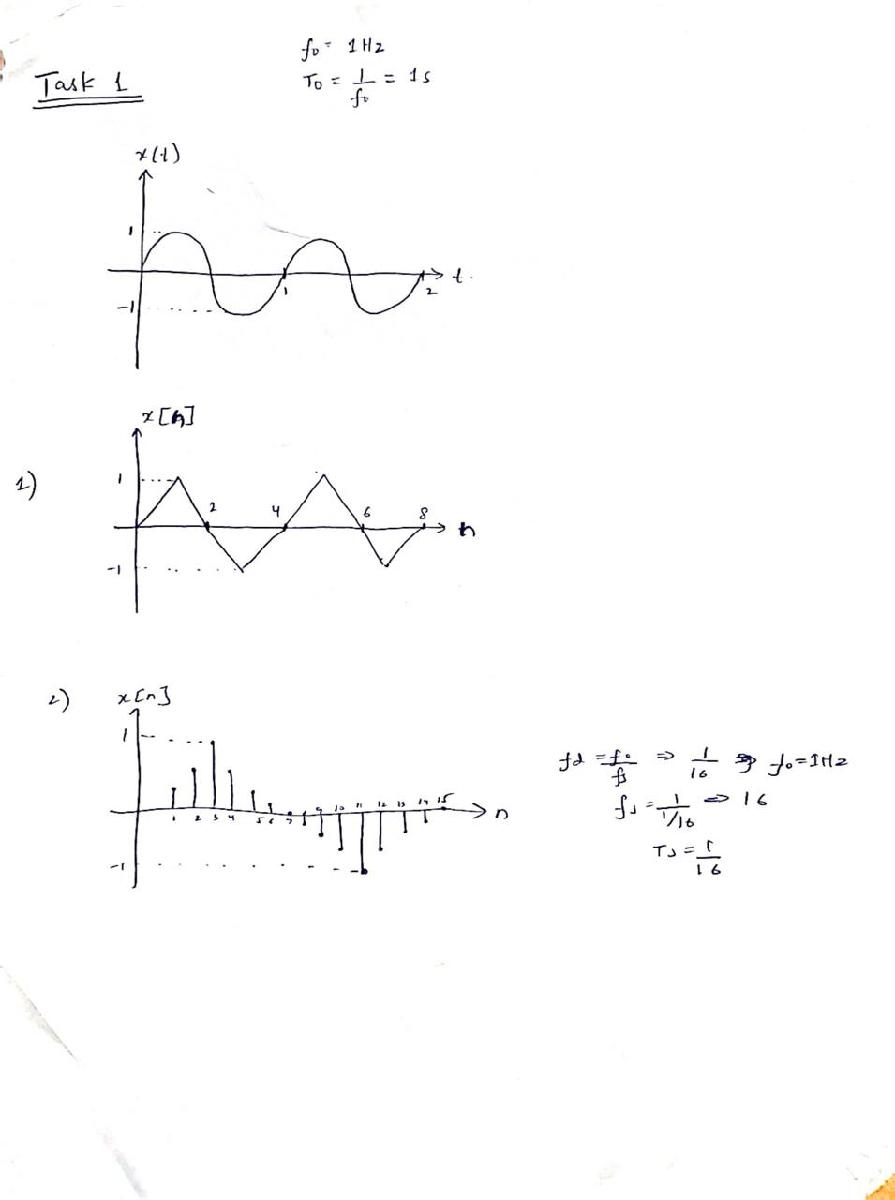

#### Task 2

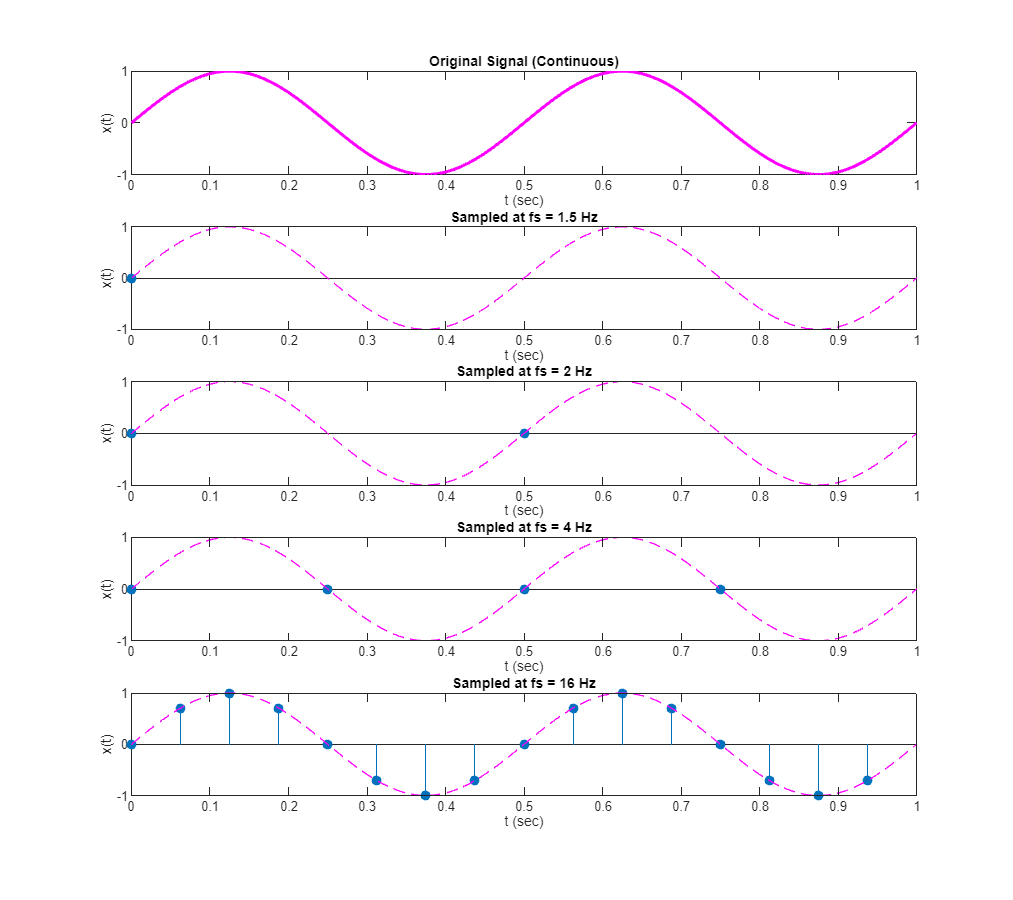

f0 = 2;              
dur = 1;             
T0 = 1/f0;           
fs = 4;              
Ts = 1/fs;           
stepsize = 0.01;     
tt = 0:stepsize:dur; % Time vector for continuous signal
xx = sin(2*pi*f0*tt); % Generate continuous sine wave signal
 % Sampled version of the signal at fs = 4 Hz (initial case)
[x, t] = sampled(f0, fs, dur); % Custom sampled() function should return sampled values and time
% Increase figure size for better visual clarity
figure('Position', [100, 100, 900, 800]);
% Plot original continuous signal
subplot(5,1,1)
plot(tt, xx, 'm', 'LineWidth', 2) % Plot continuous signal
xlabel("t (sec)")
ylabel("x(t)")
title("Original Signal (Continuous)")
hold on
% Sampling frequencies to compare: fs < 2f0, fs = 2f0, fs = 4f0, fs >> 2f0
fs2 = [1.5, 2, 4, 16];
% Loop through different sampling rates and plot sampled signals
for i = 1:4
   t_new = 0:1/fs2(i):dur - 1/fs2(i);      
% Time vector for sampled signal
   [x_new, t_new] = sampled(f0, fs2(i), dur); % Sample the signal with each fs
   subplot(5,1,i+1)                         
% Subplot for each sampled signal
   stem(t_new, x_new, 'filled')            
   hold on
   plot(tt, xx, 'm--')                     
% Plot sampled points using stem
% Overlay continuous signal for comparison
    title(['Sampled at fs = ', num2str(fs2(i)), ' Hz'])
    xlabel('t (sec)')
    ylabel('x(t)')
end

Raising the sampling frequency results in more samples per cycle, which led to poorer reconstruction quality. However, this issue did not occur with 16 samples per cycle, as it provided a more accurate estimate and thus a better reconstruction

#### Task 3

warning off
Fs=16000;%Sampling frequency in hertz e.g 1000Hz
ch=1;%Number of channels--2 options--1 (mono) or 2 (stereo)
datatype='uint8';
nbits=16;%8,16,or 24
Nseconds=5;
% to record audio data from an input device such as a microphone
recorder=audiorecorder(Fs,nbits,ch);
disp('Start speaking..')

Start speaking..


%Records audio to audiorecorder, holds control until recording completes
recordblocking(recorder,Nseconds);
disp('End of Recording.');

End of Recording.


%Stores recorded audio signal in numeric array
x=getaudiodata(recorder,datatype);
%Write audio file
audiowrite('test_task3.wav',x,Fs);

Increasing the sampling frequency (𝑓𝑠 ) results in clearer and more realistic sound reproduction, closely resembling real-life audio. As 𝑓𝑠 increases, more samples are captured per second, leading to a more detailed representation of the original sound. However, this also increases the amount of stored data, resulting in larger file sizes.

#### Task 4

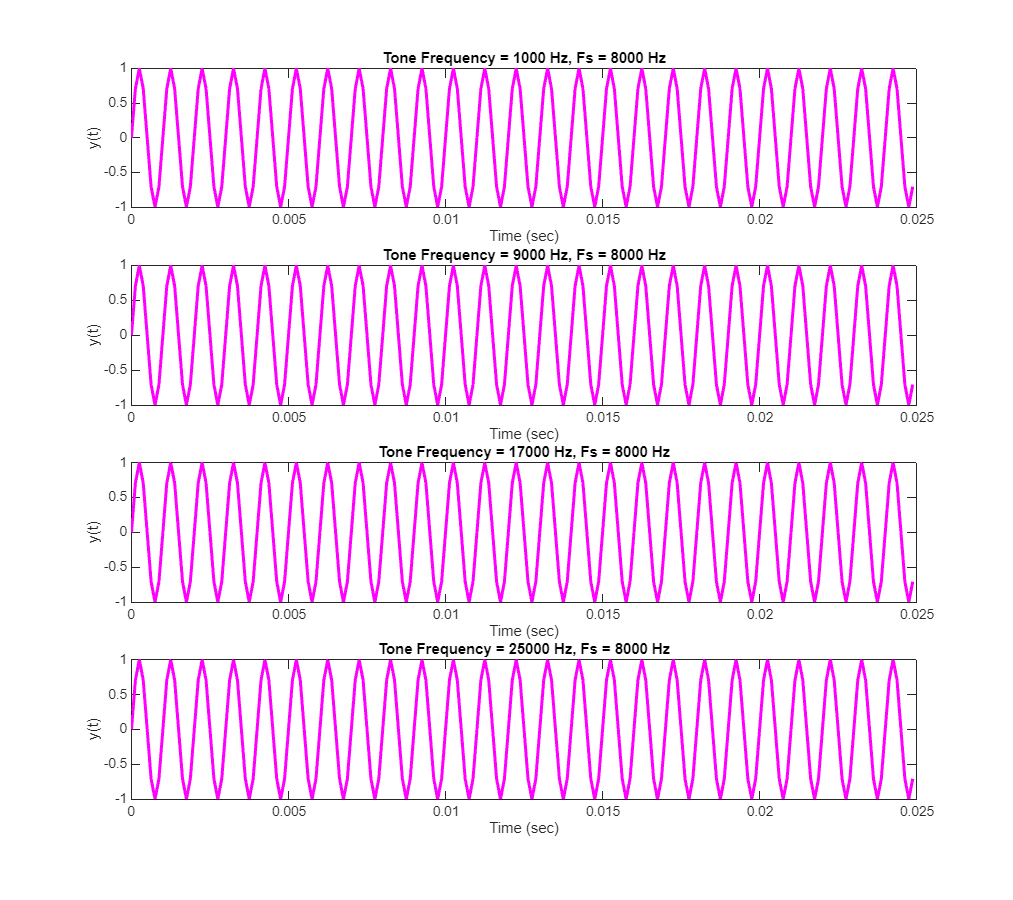

% Generate and play sine tones at different frequencies using 8000 Hz sampling rate
fs = 8000; % Fixed sampling frequency (Hz)
t = 0:1/fs:3; % Time vector for 3 seconds duration
f0 = [1000, 9000, 17000, 25000]; % Different tone frequencies to analyze
figure('Position', [100, 100, 900, 800]); % Increased figure size
for i = 1:4
   y = sin(2*pi*f0(i)*t); % Generate sine wave for the current frequency
   sound(y, fs); % Play the tone at 8000 Hz sampling rate 
   subplot(4,1,i); % Create subplot for each frequency
   plot(t(1:200), y(1:200), 'm', 'LineWidth', 2); % Plot first 200 samples for visual clarity
   ylabel('y(t)');
   xlabel('Time (sec)');
   title(['Tone Frequency = ', num2str(f0(i)), ' Hz, Fs = 8000 Hz']); 
   pause(3.5); % Wait for sound playback to finish before proceeding
end

Despite their different frequencies, the audio playback of these tones also sounds nearly indistinguishable. This indicates that the original frequency information is not accurately preserved in either the visual representation or the playback.

This unexpected behavior is due to aliasing, which occurs when the sampling frequency (8000 Hz) is insufficient to capture high-frequency signals correctly. Since the sampling rate here was 8000 Hz, any frequency above 4000 Hz gets aliased (folded back) into the audible range, producing misleading plots and sounds. Although humans typically cannot hear frequencies above 20 kHz, the 25 kHz tone was still audible due to Aliasing in the playback system and Distortion & Nonlinearities.

#### Task 5

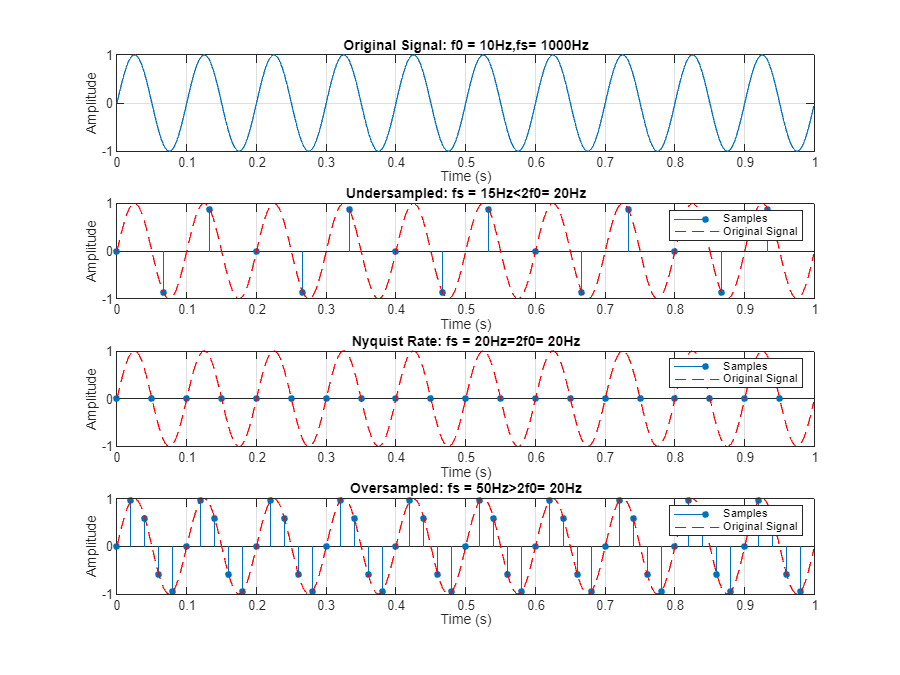

f0 = 10;% Signal frequency (Hz)
duration = 1;
fs_high = 1000;
t_high = 0:1/fs_high:duration-1/fs_high;
x_original = sin(2*pi*f0*t_high);
% Case i(Undersampling)
fs_under = 15;
t_under = 0:1/fs_under:duration-1/fs_under;
x_under = sin(2*pi*f0*t_under);
% Case ii (Exact Nyquist rate)
fs_nyquist = 2*f0;
t_nyquist = 0:1/fs_nyquist:duration-1/fs_nyquist;
x_nyquist = sin(2*pi*f0*t_nyquist);
% Case iii (Oversampling)
fs_over = 5*f0;
t_over = 0:1/fs_over:duration-1/fs_over;
x_over = sin(2*pi*f0*t_over);
figure;
subplot(4,1,1);
plot(t_high, x_original);
title(['Original Signal: f0 = ' num2str(f0) 'Hz,fs= ' num2str(fs_high) 'Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
subplot(4,1,2);
stem(t_under, x_under,'fill','MarkerSize',4);
hold on;
plot(t_high, x_original, 'r--');
hold off;
title(['Undersampled: fs = ' num2str(fs_under) 'Hz<2f0= ' num2str(2*f0) 'Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('Samples', 'Original Signal');
subplot(4,1,3);
stem(t_nyquist, x_nyquist, 'fill', 'MarkerSize', 4);
hold on;
plot(t_high, x_original, 'r--');
hold off;
title(['Nyquist Rate: fs = ' num2str(fs_nyquist) 'Hz=2f0= ' num2str(2*f0) 'Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('Samples', 'Original Signal');
subplot(4,1,4);
stem(t_over, x_over, 'fill', 'MarkerSize', 4);
hold on;
plot(t_high, x_original, 'r--');
hold off;
title(['Oversampled: fs = ' num2str(fs_over) 'Hz>2f0= ' num2str(2*f0) 'Hz']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
legend('Samples', 'Original Signal');
set(gcf, 'Position', [100, 100, 800, 600]);

Case 1 (fs < 2f0):

The sampled signal does not accurately represent the original waveform. Neither the period nor the shape matches the analog signal, resulting in significant distortion.

Case 2 (fs = 2f0):

While the sampled signal eventually captures the correct period after several cycles, it still fails to reproduce the smooth waveform accurately. Instead, it appears as a rough approximation, resembling a triangular wave rather than the original signal.

Case 3 (fs > 2f0): 

Here, the sampled signal closely follows both the period and shape of the original analog signal, enabling faithful reconstruction.

This experiment clearly validates the Nyquist Theorem, which states that the sampling frequency must exceed twice the highest frequency component (fs > 2f0) to reconstruct an analog signal accurately from its discrete samples